function [Ck]=fourier_series_exp(x,t,Nk,p)

% Ck = exponential fourier series cofficient  
% x = single period of a signal
% t = time corrosponding to 'x'
% Nk = (optional input) number of exponential terms
% p = plotting option ; p=0, no plots, p = 1 plot Ck vs k and reconstructed signal 
% dT = t(2)-t(1) = temporal resolution of signal (x)
% T = peiod of signal 'x'
% w0= angular frequency of signal 'x' 


    dT=t(2)-t(1);
    T= dT*length(t);
    w0=2*pi/T;   

    % Check the number of inputs, 'nargin' returns number of input arguments 
    if nargin <2
        error('Not enough input argument!')
    elseif nargin == 2
        Nk=101;  % you can set any default value you like 
        p=0;  % not plots
    elseif nargin ==3
        p=0; % not plots
    end
    k=-floor(Nk/2):floor(Nk/2); % if Nk=11, k=-5:5; if Nk=12, k=-6:6


    %% evaluate Ck
    for ii=1:length(k)
        Ck(ii)=(1/T)*trapz(t, x.*exp(-j*k(ii)*w0*t));
    end
    
    
%% plot spectrum and reconstructed signal     
    if p==1
        % plot abs(Ck) vs k and angle(Ck) vs k
        figure 
        subplot(211)
        stem(k,abs(Ck))
        xlabel('k')
        ylabel('|C_k|')
        
        w0k = w0*k;
        subplot(2,1,2)
        stem(w0k,angle(Ck)*180/pi);  
        xlabel('k')
        ylabel('\angleC_k')
        
        % plot 3 cycles of the signal 'x' and the reconstructed signal
        x_ext=repmat(x,1,3);
        t_ext=t(1):dT:t(1)+(3*length(t)-1)*dT;

        x_reconstructed=zeros(size(t_ext));
        for ii=1:length(k)
            x_reconstructed=x_reconstructed+Ck(ii)*exp(j*k(ii)*w0*t_ext);
        end
        figure
        subplot(211)
        plot(t_ext,x_ext)
        xlabel('t');
        title('original signal')
        subplot(2,1,2)
        plot(t_ext,x_reconstructed)
        xlabel('t');
        title('reconstructed signal')
    end
     
end

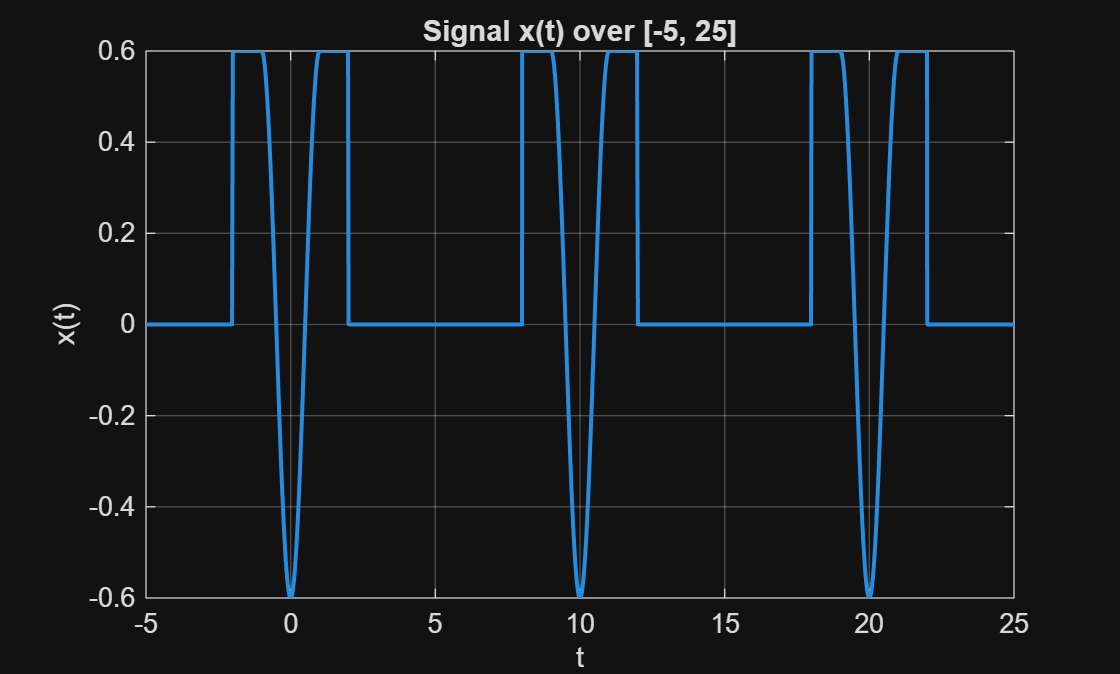

%2.
% Define time for one period
T = 10;                  % Period
Fs = 1000;               % Sampling frequency (points per second)
dt = 1/Fs;
t_period = -5:dt:5-dt;   % One period [-5,5)

% Define the signal for one period
x_period = 0.6 * ( ...
    heaviside(t_period + 2) ...
    - (cos(pi*t_period) + 1) .* (heaviside(t_period + 1) - heaviside(t_period - 1)) ...
    - heaviside(t_period - 2) ...
);

% Plot signal from -5 to 25 (3 periods)
x_extended = repmat(x_period, 1, 3);   % Repeat 3 times
t_extended = -5:dt:25-dt;

figure;
plot(t_extended, x_extended, 'LineWidth', 1.5);
xlabel('t');
ylabel('x(t)');
title('Signal x(t) over [-5, 25]');
grid on;

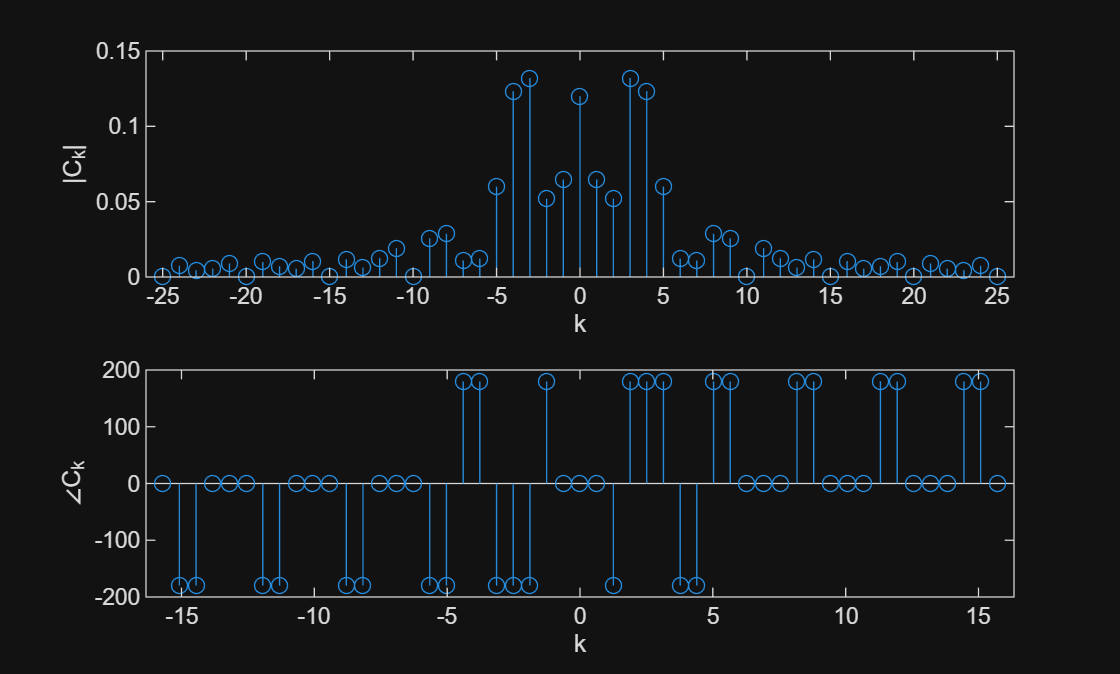

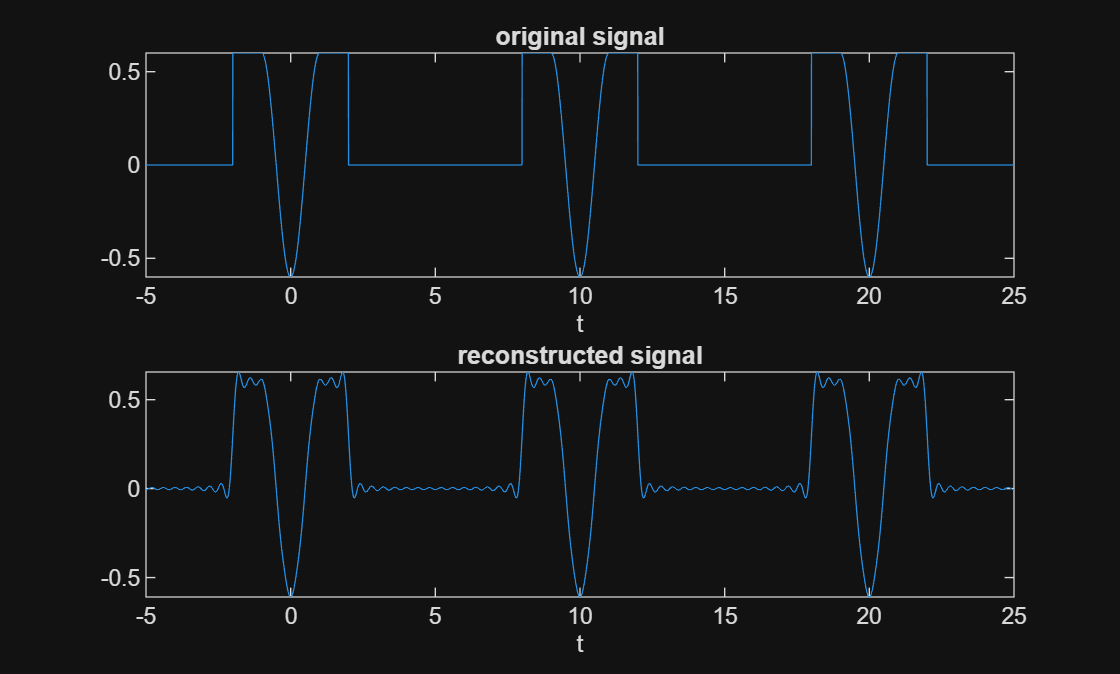


% Compute Fourier Series coefficients & plot spectrum + reconstruction
Nk = 51;  % Number of coefficients
Ck = fourier_series_exp(x_period, t_period, Nk, 1);

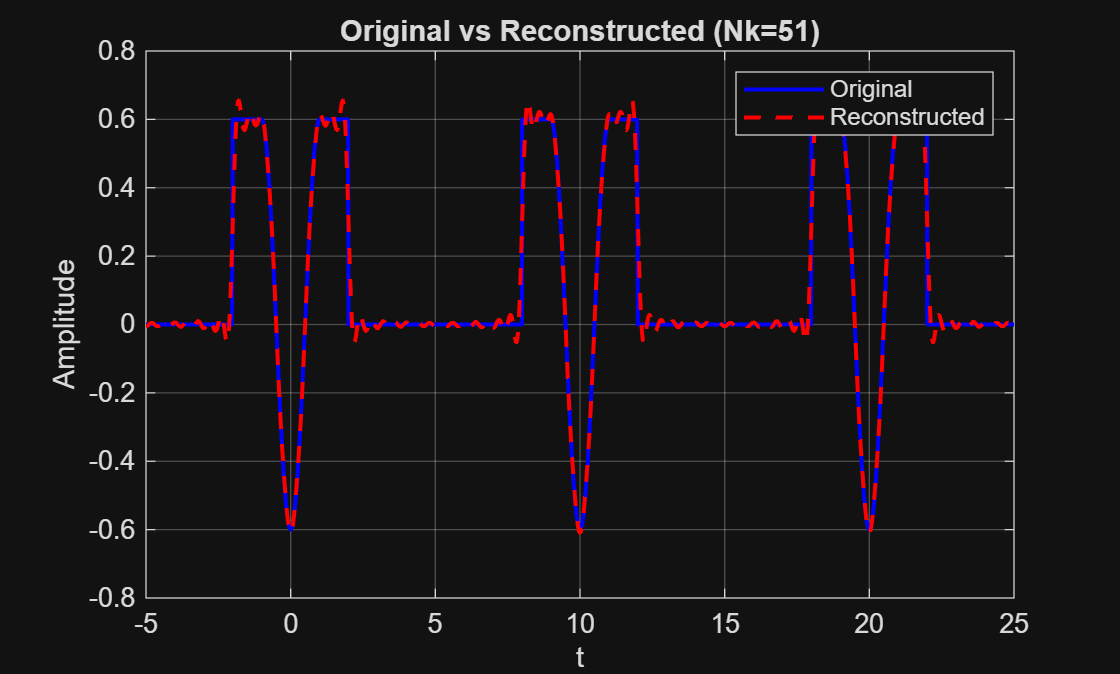


% OPTIONAL: Reconstructed signal using Nk coefficients
w0 = 2*pi/T;
k = -floor(Nk/2):floor(Nk/2);
x_rec = zeros(size(t_extended));
for ii = 1:length(k)
    x_rec = x_rec + Ck(ii)*exp(1j*k(ii)*w0*t_extended);
end

figure;
plot(t_extended, real(x_extended), 'b', 'LineWidth', 1.5); hold on;
plot(t_extended, real(x_rec), 'r--', 'LineWidth', 1.5);
xlabel('t');
ylabel('Amplitude');
legend('Original','Reconstructed');
title('Original vs Reconstructed (Nk=51)');
grid on;

%x_single_period(t)= 5, 0<t<1 , T=2 
%                   -5, 1<t<2  
%x_periodic(t),     0<t<5T

close all
clear all
clc

%% single period defination
dT=0.01;
t1=0:.01:1;
t2=1.01:.01:2;
x1=5*ones(size(t1));
x2=-5*ones(size(t2));
x_single_period=[x1 x2];
t_single_period=[t1 t2]; % single period is from 0 to 2


%% period and fundamental angular freq.
T=2;
w0=2*pi/T; 


%%



%% replicating single period
number_of_periods=5;
x_extended=repmat(x_single_period,1,number_of_periods);   % 1 row, 5 column: number of periods
% generating new 'time' variable to match signal 'x_extended'
t_extended=linspace(t_single_period(1),t_single_period(1)+(length(x_extended)-1)*...
    (t_single_period(2)-t_single_period(1)),length(x_extended));


figure (1)
subplot(211)
plot(t_extended,x_extended);
xlabel('t')
title('original signal')
xlim([0 10])



%% exponential FS, approximation with 11 terms
k=-2:2; %k=index of harmonics

for ii=1:length(k)
    Ck(ii)=(1/T)*trapz(t_single_period, x_single_period.*exp(-j*k(ii)*w0*t_single_period))
end

Ck = 0.0250 - 0.0000i

Ck =    0.0250 - 0.0000i  -0.0250 + 3.1828i


Ck =    0.0250 - 0.0000i  -0.0250 + 3.1828i   0.0250 + 0.0000i


Ck =    0.0250 - 0.0000i  -0.0250 + 3.1828i   0.0250 + 0.0000i  -0.0250 - 3.1828i


Ck =    0.0250 - 0.0000i  -0.0250 + 3.1828i   0.0250 + 0.0000i  -0.0250 - 3.1828i   0.0250 + 0.0000i


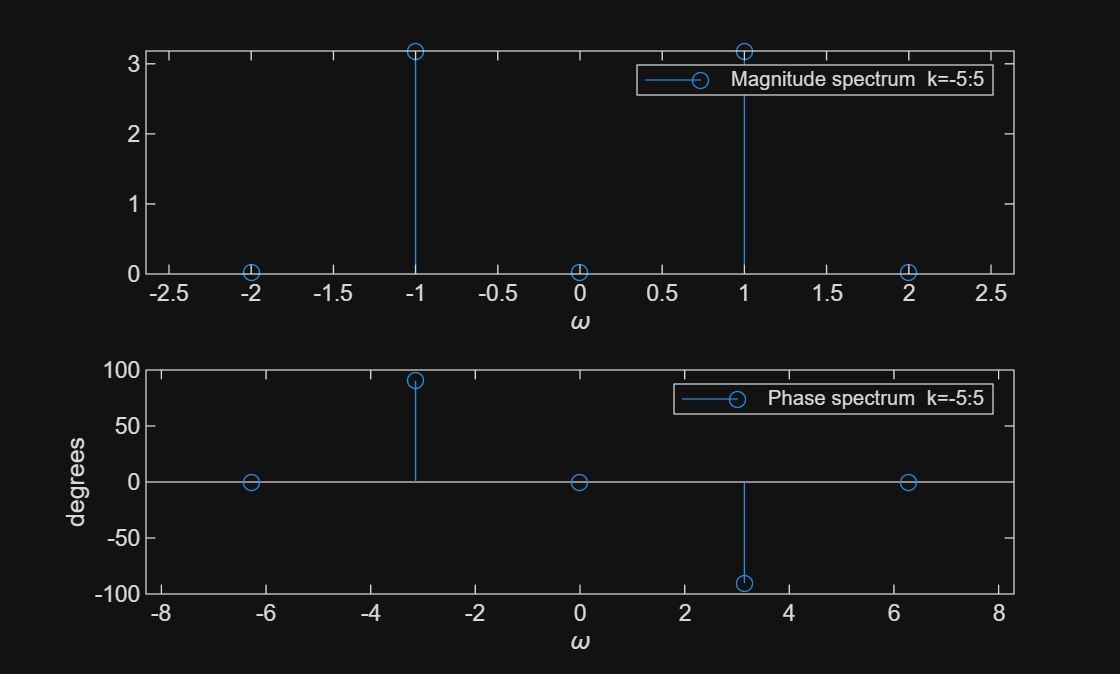


w0k=w0*k;  % different hermonic angular frequencies
figure (2)
subplot(211)
stem(k,abs(Ck))
hold on
% set(gca,'xtick',w0k,'xticklabels',{'-5\omega_0','-4\omega_0',...
%     '-3\omega_0','-2\omega_0','-\omega_0','0','\omega_0',...
%     '2\omega_0','3\omega_0','4\omega_0','5\omega_0'});

legend('Magnitude spectrum  k=-5:5')
xlabel('\omega')

subplot(212)
stem(w0k,angle(Ck)*180/pi);
% set(gca,'xtick',w0k,'xticklabels',{'-5\omega_0','-4\omega_0',...
%     '-3\omega_0','-2\omega_0','-\omega_0','0','\omega_0',...
%     '2\omega_0','3\omega_0','4\omega_0','5\omega_0'});
legend('Phase spectrum  k=-5:5')
xlabel('\omega')
ylabel('degrees')


%% signal reconstruction from FS components
% reconstructing 'number_of_periods' cycles


t_reconstracted=linspace(t_single_period(1),t_single_period(1)+...
    (number_of_periods*length(t_single_period)-1)*(t_single_period(2)-t_single_period(1)),...
    number_of_periods*length(x_single_period));

x_reconstracted=zeros(1,length(t_reconstracted));  % initiating with zeros (0)


for ii=1:length(k)
    x_reconstracted=x_reconstracted+Ck(ii)*exp(j*k(ii)*w0*t_reconstracted);
end

figure(1)
subplot(212)
plot(t_reconstracted,x_reconstracted)

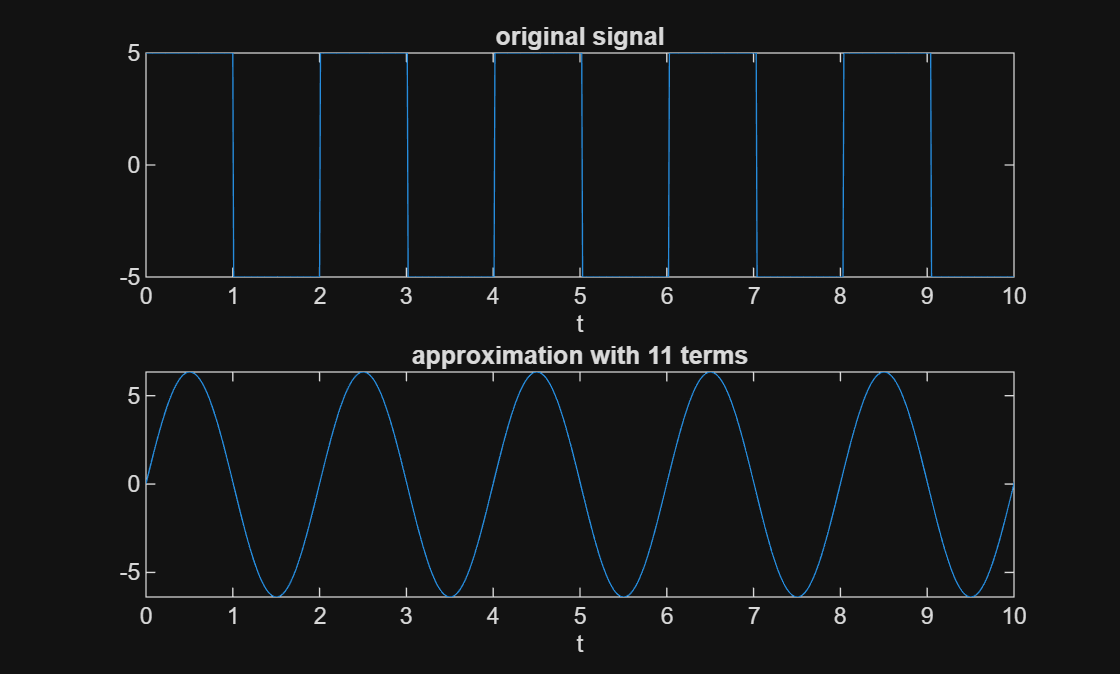

xlabel('t');
title('approximation with 11 terms')
xlim([0 10])

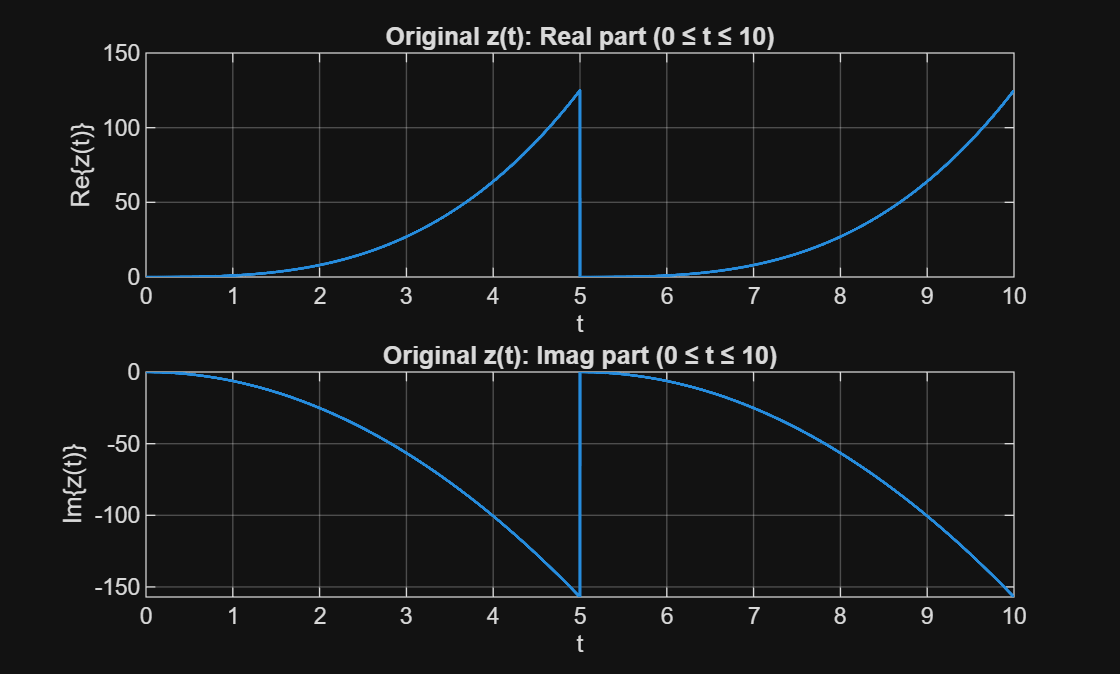

%3.
% z(t) = t^3 - j*2*pi*t^2 on 0 < t <= 5, periodic with T=5
% Compute 51 FS coefficients and reconstruct over 0 <= t <= 10

close all; clear; clc;

%% Single-period definition
T = 5;
w0 = 2*pi/T;

% Time grid for one period (exclude t=0 endpoint duplication at wrap)
dt = 1e-3;                    % sufficiently fine for accurate trapz
t_single = 0:dt:T-dt;         % [0, T)
z_single = (t_single.^3) - 1j*2*pi*(t_single.^2);

%% Replicate to visualize original over 0..10 (two periods)
numPeriods = 2;
z_extended = repmat(z_single, 1, numPeriods);
t_extended = linspace(t_single(1), ...
    t_single(1) + (length(z_extended)-1)*dt, length(z_extended));

figure(1); clf;
subplot(2,1,1);
plot(t_extended, real(z_extended), 'LineWidth', 1.2);
xlabel('t'); ylabel('Re\{z(t)\}');
title('Original z(t): Real part (0 ≤ t ≤ 10)'); grid on; xlim([0 10]);

subplot(2,1,2);
plot(t_extended, imag(z_extended), 'LineWidth', 1.2);
xlabel('t'); ylabel('Im\{z(t)\}');
title('Original z(t): Imag part (0 ≤ t ≤ 10)'); grid on; xlim([0 10]);

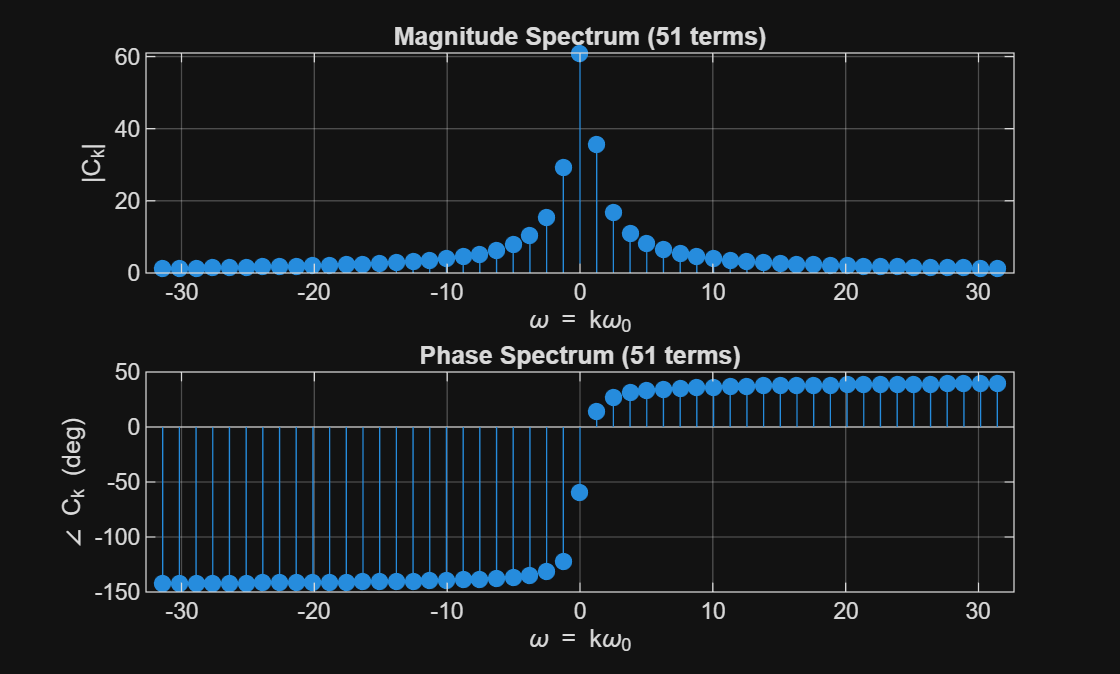


%% Exponential FS: 51 terms (k=-25:25)
Nk = 51;
k = -floor(Nk/2):floor(Nk/2);

Ck = zeros(size(k));
for ii = 1:length(k)
    % Numerical integral over one period (trapz)
    Ck(ii) = (1/T) * trapz(t_single, z_single .* exp(-1j*k(ii)*w0*t_single));
end

% (Optional) exact DC term override for extra accuracy:
C0_exact = (T^3)/4 - 1j*(2*pi*T^2)/3;
Ck(k==0) = C0_exact;

%% Spectrum plots: |Ck| and angle(Ck) vs omega = k*w0
w = w0 * k;

figure(2); clf;
subplot(2,1,1);
stem(w, abs(Ck), 'filled'); grid on;
xlabel('\omega = k\omega_0'); ylabel('|C_k|');
title('Magnitude Spectrum (51 terms)');

subplot(2,1,2);
stem(w, angle(Ck)*180/pi, 'filled'); grid on;
xlabel('\omega = k\omega_0'); ylabel('\angle C_k (deg)');
title('Phase Spectrum (51 terms)');

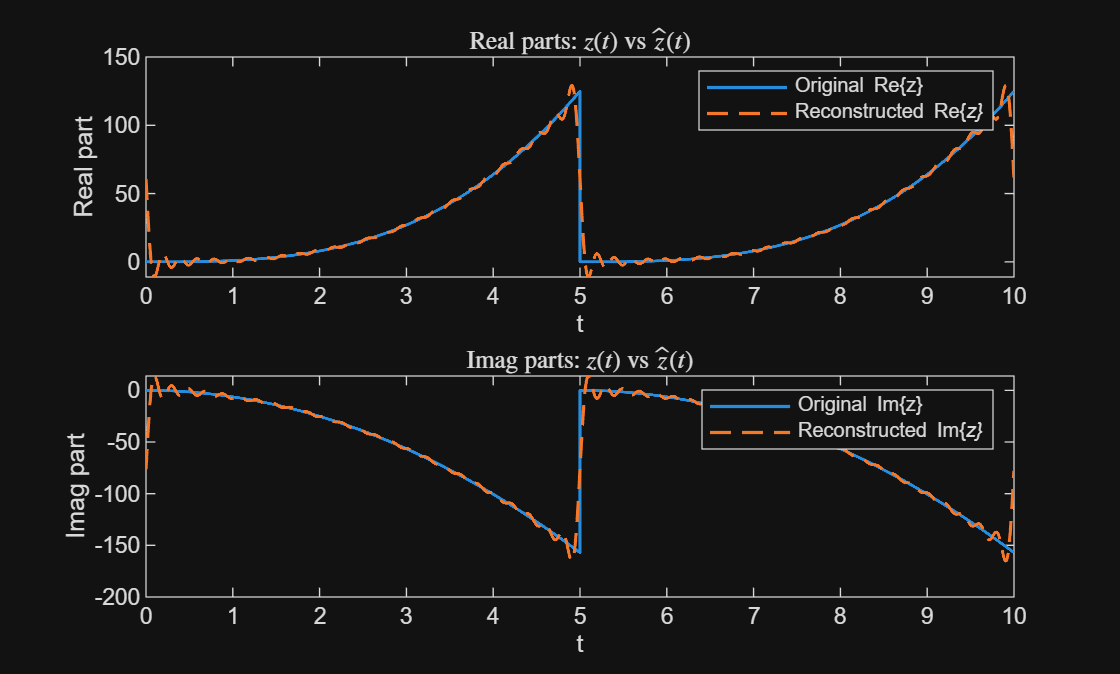


%% Reconstruction on 0..10 with the same dt and number of samples
t_rec = t_extended;                     % match 0..10 timeline
z_rec = zeros(size(t_rec));
for ii = 1:length(k)
    z_rec = z_rec + Ck(ii) * exp(1j*k(ii)*w0*t_rec);
end

%% Plot reconstructed vs original (real and imag)
figure(3); clf;
subplot(2,1,1);
plot(t_rec, real(z_extended), 'LineWidth', 1.2); hold on;
plot(t_rec, real(z_rec), '--', 'LineWidth', 1.2);
xlabel('t'); ylabel('Real part');
legend('Original Re\{z\}','Reconstructed Re\{\itz\}');
title('Real parts: $z(t)$ vs $\hat{z}(t)$', 'Interpreter', 'latex');

subplot(2,1,2);
plot(t_rec, imag(z_extended), 'LineWidth', 1.2); hold on;
plot(t_rec, imag(z_rec), '--', 'LineWidth', 1.2);
xlabel('t'); ylabel('Imag part');
legend('Original Im\{z\}','Reconstructed Im\{\itz\}');
title('Imag parts: $z(t)$ vs $\hat{z}(t)$', 'Interpreter', 'latex');